# Molico (2006) Replication

## Calibration

clear all
close all
clc

tic

mupper=3 %highest value if money holdings on the grid

mupper = 3

N=100%number of agents for simulating distribution

N = 100

iterations=20 %maximum number of iterations for the value function iteration)

iterations = 20

%need at least around 15-20 iterations to make distribution converge

stopping_parameter=0 %the smaller, the more does it iteration take to converge

stopping_parameter = 0

x=0.25

x = 0.2500

alpha=1

alpha = 1

theta=1

theta = 1

beta=0.99 %discount factor

beta = 0.9900

M=1 %Money supply (leave at one if inflation>0)

M = 1

r=1/beta-1 %real interest rate

r = 0.0101

mu_all=[0,0.1] %Money Growth

mu_all =          0    0.1000


mu_labels={ 'Price Stability','10%-Inflation'}

mu_labels = 1×2 cell array
    {'Price Stability'}    {'10%-Inflation'}


n_calibration=size(mu_all)

n_calibration =      1     2


n_calibration=n_calibration(1,2)

n_calibration = 2

smoothing_parameter=0.3

smoothing_parameter = 0.3000

correct_dist=1

correct_dist = 1

## Define grid

% sets up a grid where points are located around 50-100 since under the
% most used calibration, many agents were holding money holdings in that
% range
% grids_1=8
% grids_2=8
% grids_3=3
% grids=grids_1+grids_2+grids_3
% 
% m_0=linspace(0,0.80,grids_1)
% m_1=linspace(0.90,2, grids_2)
%  m_2=linspace(2.1,mupper,grids_3);
%  m=[m_0,m_1,m_2]
grids=10

grids = 10

m=linspace(0,mupper, grids)

m =          0    0.3333    0.6667    1.0000    1.3333    1.6667    2.0000    2.3333    2.6667    3.0000


%EXPLANATION: NON-LINEAR GRID SPACES LEADS TO APPROXIMATION ERRORS SUCH
%THAT THE "REAL MONEY SUPPLY" GROWS OVER ITERATIONS. 


## Options



test_interpolation=0; % checks the interpolation method and displays the initial guess of the value function

display_plot_all=1;

display_plot_Distribution_rough=0;
display_plot_Distribution_smooth=1;
display_plot_cdf=0;
display_plot_M_Track_1=1;
display_plot_V=1;
display_plot_q_all=1;
display_plot_d_all=1;


display_plot_q=0;
display_plot_d=0;
display_plot_meeting=0;
display_plot_money_savings=0;
display_plot_functional_forms=0;



## set up matrixes

initial_distribution_shock=ones(1,N);
Distribution_number=ones(1,N);
Distribution_0=ones(1,N);
cdf_0=zeros(1,grids);
lamdba_0=zeros(1,grids);
m_savings_1=zeros(1,grids);
m_savings_2=zeros(1,grids);
m_savings_3=zeros(1,grids);

V_all=zeros(grids,n_calibration);
Distribution_all=zeros(N,n_calibration);
q_all=zeros(grids, grids,n_calibration);
d_all=zeros(grids, grids,n_calibration);
lamdba_all=zeros(grids,n_calibration);
price_all=zeros(grids, grids,n_calibration);
f=zeros(100,n_calibration);
xi=zeros(100,n_calibration);
M_track_1=zeros(iterations,n_calibration);

average_price=zeros(1,n_calibration);
std_distribution=zeros(1,n_calibration);
velocity=zeros(1,n_calibration);
average_real_balances=zeros(1,n_calibration);
average_q=zeros(1,n_calibration);

## Initial Guess

% set an initial guess for the value function
V0=log(1+m)*100  ;

 
% set an initial guess for the pdf distributiuon

for j=1:grids
if m(1,j)>M
lamdba_0(1,j)=1;
break
end
end



M_0=lamdba_0*m';

%ISSUE: the guess was choosen such that that the implied money supply is
%equal to M. But then the pdf does not sum to 1. I don't think this is a
%problem since after 


% compute cdf
for i=1:grids-1
    cdf_0(1,1)=lamdba_0(1,1);
cdf_0(1,i+1)=cdf_0(1,i)+lamdba_0(1,1+i);
end


% Draw from the initial guess
% we draw a random shock [0,1] for each individual in N. Depending on the
% initial guess, the cdf will determine the distributiuon. Notice, the
% distribution_number is determined to determine the grid point which can
% then be used to determine the money holding by using the grid m

found=0; %this parameter indicates whether a certain condition in the loop was satisfied
for i=1:N
initial_distribution_shock(1,i)=unifrnd(0,1); 
for l=1:grids 
   if initial_distribution_shock(1,i)<cdf_0(1,l)
Distribution_number(1,i)=l;
Distribution_0(1,i)=m(1,Distribution_number(1,i));
found=1;
   end
    
if found==1
found=0;
    break
end
       
end

end

 


## Iteration

 for calibriation=1:n_calibration
mu=mu_all(1,calibriation);
[V_all(:,calibriation), q_all(:,:,calibriation),d_all(:,:,calibriation),Distribution_all(:,calibriation),...
    lamdba,cdf,M_track_1(:,calibriation), M_track_2,Meeting,i] = Iter_Molico_06(iterations, N,m...
     ,grids,V0,lamdba_0, cdf_0,Distribution_0,M_0,r,alpha,x,mu,theta,mupper, stopping_parameter,correct_dist);
% 
%  if cdf(grids)==1
%     disp('cdf adds up to one')
% else 
%     disp('cdf does not add up to one')
%     cdf(grids)
%  end



Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>

Local minimum found that satisfies the constraints.

Optimization completed because the objective fu

stop = 0


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>

Local minimum found that satisfies the constraints.

Optimization completed because the objective fu

k = 1

M_distribution =   133.3333         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Distribution_new =     1.1916    1.4751    1.1916    1.4751    1.3333    1.4751    1.1916    1.3333    1.1916    1.4751    1.1916    1.4751    1.3333    1.3333    1.3333    1.4751    1.1916    1.4751    1.1916    1.4751    1.1916    1.4751    1.1916    1.3333    1.4751    1.1916    1.1916    1.4751    1.3333    1.1916    1.4751    1.3333    1.1916    1.4751    1.3333    1.4751    1.1916    1.4751    1.1916    1.3333    1.3333    1.3333    1.1916    1.4751    1.4751    1.1916    1.4751    1.1916    1.3333    1.3333


Value function has not converged


i = 1


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>

Local minimum found that satisfies the constraints.

Optimization completed because the objective fu

k = 1

M_distribution =   133.3333  133.3333         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Distribution_new =     1.1916    1.6311    1.0356    1.6195    1.1889    1.6195    1.0471    1.1926    1.3323    1.4751    1.0498    1.6168    1.3333    1.4741    1.1926    1.6195    1.0471    1.4751    1.3272    1.3394    1.3272    1.3394    1.1916    1.1926    1.6158    1.1916    1.1916    1.6311    1.1774    1.1916    1.3291    1.4793    1.0573    1.6093    1.3333    1.3291    1.3376    1.3209    1.3458    1.3333    1.3333    1.3333    1.0573    1.6093    1.3291    1.3376    1.4751    1.3272    1.1977    1.4741


Value function has not converged


i = 2


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>

Local minimum found that satisfies the constraints.

Optimization completed because the objective fu

k = 1

M_distribution =   133.3333  133.3333  133.3333         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Distribution_new =     1.3257    1.4970    0.9008    1.7544    1.1889    1.4701    1.1966    1.3267    1.1982    1.4751    0.9146    1.7521    1.1940    1.6134    1.0518    1.7604    1.1768    1.3454    1.1801    1.4866    1.3272    1.3394    1.1916    1.1926    1.7621    1.0453    1.1916    1.6311    1.3219    1.0470    1.4683    1.3401    1.0573    1.6093    1.4843    1.1781    1.4771    1.1814    1.3458    1.3333    1.1940    1.4727    1.0573    1.7554    1.1830    1.1980    1.6146    1.3272    1.3431    1.3287


Value function has not converged


i = 3


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>

Local minimum found that satisfies the constraints.

Optimization completed because the objective fu

k = 1

M_distribution =   133.3333  133.3333  133.3333  133.3333         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Distribution_new =     1.3257    1.4970    0.9008    1.5923    1.3510    1.4701    1.1966    1.4763    1.0486    1.4751    1.0540    1.6127    1.1940    1.4563    1.2089    1.7604    1.1768    1.3454    1.3237    1.3429    1.3272    1.3394    1.3242    1.0599    1.6092    1.1982    1.1916    1.4732    1.4798    1.1756    1.3397    1.3401    1.1971    1.4695    1.6264    1.0360    1.6314    1.0271    1.2073    1.4718    1.0537    1.6130    0.9219    1.8909    1.1830    1.3424    1.4703    1.3272    1.5038    1.1680


Value function has not converged


i = 4


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>

Local minimum found that satisfies the constraints.

Optimization completed because the objective fu

k = 1

M_distribution =   133.3333  133.3333  133.3333  133.3333  133.3333         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Distribution_new =     1.4741    1.3485    0.7758    1.7172    1.2138    1.6073    1.1966    1.4763    1.1877    1.3360    1.0540    1.4757    1.3310    1.4563    1.2089    1.6086    1.3286    1.3454    1.1789    1.4877    1.3272    1.1940    1.4696    1.0599    1.7659    1.0415    1.0690    1.5958    1.3377    1.3177    1.4765    1.2034    1.3288    1.3378    1.6264    1.1750    1.4925    0.8921    1.3423    1.6249    0.9006    1.6130    0.7889    2.0239    1.3142    1.2112    1.6108    1.1867    1.6577    1.0140


Value function has not converged


i = 5


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>

Local minimum found that satisfies the constraints.

Optimization completed because the objective fu

k = 1

M_distribution =   133.3333  133.3333  133.3333  133.3333  133.3333  133.3333         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Distribution_new =     1.6261    1.1965    0.7758    1.8627    1.0683    1.4444    1.3595    1.4763    1.3182    1.2055    1.0540    1.6151    1.1915    1.5952    1.0700    1.4631    1.4741    1.2096    1.3147    1.3376    1.4774    1.1940    1.4696    1.1874    1.6384    1.0415    0.9328    1.7320    1.3377    1.3177    1.6159    1.0639    1.1936    1.4730    1.6264    1.1750    1.4925    1.0314    1.2030    1.4788    1.0467    1.6130    0.9285    1.8843    1.3142    1.3542    1.4677    1.0560    1.7885    0.8722


Value function has not converged


i = 6


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>

Local minimum found that satisfies the constraints.

Optimization completed because the objective fu

k = 1

M_distribution =   133.3333  133.3333  133.3333  133.3333  133.3333  133.3333  133.3333         0         0         0         0         0         0         0         0         0         0         0         0         0


Distribution_new =     1.4715    1.3511    0.9142    1.7244    0.9247    1.5880    1.3595    1.3278    1.4667    1.3359    0.9236    1.6151    1.0609    1.7258    1.1974    1.3357    1.4741    1.2096    1.3147    1.2030    1.6119    1.1940    1.4696    1.1874    1.6384    0.9144    1.0599    1.7320    1.2032    1.4522    1.4713    1.2085    1.1936    1.4730    1.6264    1.3263    1.3411    1.0314    1.3334    1.3484    1.1950    1.4647    0.9285    1.7307    1.4678    1.2102    1.6117    1.0560    1.7885    0.9997


Value function has not converged


i = 7


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>

Local minimum found that satisfies the constraints.

Optimization completed because the objective fu

k = 1

M_distribution =   133.3333  133.3333  133.3333  133.3333  133.3333  133.3333  133.3333  133.3333         0         0         0         0         0         0         0         0         0         0         0         0


Distribution_new =     1.4715    1.3511    1.0411    1.5975    0.8012    1.7115    1.3595    1.3278    1.4667    1.2022    1.0573    1.7481    0.9279    1.8617    1.0615    1.3357    1.3359    1.3479    1.3147    1.2030    1.6119    1.3238    1.3398    1.0571    1.7687    0.7913    1.1831    1.7320    1.2032    1.4522    1.6208    1.0590    1.3347    1.3319    1.6264    1.3263    1.3411    1.1583    1.2065    1.3484    1.1950    1.4647    0.7969    1.8623    1.4678    1.0794    1.7425    1.1942    1.6503    1.1264


Value function has not converged


i = 8


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>

Local minimum found that satisfies the constraints.

Optimization completed because the objective fu

k = 1

M_distribution =   133.3333  133.3333  133.3333  133.3333  133.3333  133.3333  133.3333  133.3333  133.3333         0         0         0         0         0         0         0         0         0         0         0


Distribution_new =     1.4715    1.3511    1.0411    1.7295    0.6691    1.5557    1.5153    1.1948    1.5998    1.0554    1.2041    1.9047    0.7714    1.7005    1.2227    1.1937    1.4779    1.2208    1.4418    1.2030    1.7524    1.1834    1.4732    0.9238    1.6207    0.9393    1.1831    1.5755    1.3597    1.5884    1.4846    1.1862    1.2075    1.3319    1.6264    1.1768    1.4906    1.0350    1.3298    1.3484    1.1950    1.3276    0.9340    2.0095    1.3206    1.0794    1.5954    1.3413    1.6503    0.9746


Value function has not converged


i = 9


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>

Local minimum found that satisfies the constraints.

Optimization completed because the objective fu

k = 1

M_distribution =   133.3333  133.3333  133.3333  133.3333  133.3333  133.3333  133.3333  133.3333  133.3333  133.3333         0         0         0         0         0         0         0         0         0         0


Distribution_new =     1.4715    1.2179    1.1743    1.5837    0.8150    1.5557    1.3835    1.3265    1.4410    1.2142    1.0653    2.0435    0.8940    1.5779    1.2227    1.1937    1.3410    1.3578    1.4418    1.0565    1.8989    1.3341    1.3225    1.0498    1.4947    1.0654    1.0569    1.4261    1.5091    1.5884    1.4846    1.0400    1.3537    1.2053    1.7530    1.0470    1.6204    0.9145    1.4503    1.2152    1.3282    1.3276    0.9340    2.1953    1.1347    0.9436    1.7313    1.3413    1.6503    1.1112


Value function has not converged


i = 10


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>

Local minimum found that satisfies the constraints.

Optimization completed because the objective fu

k = 1

M_distribution =   133.3333  133.3333  133.3333  133.3333  133.3333  133.3333  133.3333  133.3333  133.3333  133.3333  133.3333         0         0         0         0         0         0         0         0         0


Distribution_new =     1.4715    1.0645    1.3277    1.5837    0.8150    1.4079    1.5313    1.3265    1.4410    1.0898    1.1896    2.0435    0.7690    1.7028    1.2227    1.1937    1.3410    1.3578    1.2978    1.2005    1.7551    1.4778    1.1817    1.1905    1.4947    1.0654    1.0569    1.4261    1.6371    1.4605    1.4846    1.0400    1.4868    1.0722    1.5813    1.2187    1.6204    0.9145    1.4503    1.2152    1.4607    1.1950    0.9340    2.0353    1.2948    0.9436    1.8647    1.2078    1.6503    1.1112


Value function has not converged


i = 11


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>

Local minimum found that satisfies the constraints.

Optimization completed because the objective fu

k = 1

M_distribution =   133.3333  133.3333  133.3333  133.3333  133.3333  133.3333  133.3333  133.3333  133.3333  133.3333  133.3333  133.3333         0         0         0         0         0         0         0         0


Distribution_new =     1.3354    1.2006    1.4601    1.4513    0.9451    1.2778    1.3934    1.4644    1.3121    1.2187    1.1896    1.8887    0.9238    1.7028    1.0845    1.3319    1.3410    1.5006    1.1549    1.0706    1.8850    1.4778    1.0445    1.3278    1.6210    0.9391    1.0569    1.5818    1.4813    1.3082    1.6369    1.0400    1.4868    1.0722    1.4418    1.3582    1.7597    0.7752    1.3148    1.3506    1.3249    1.3308    0.9340    1.8808    1.4493    0.9436    1.8647    1.3379    1.5202    1.1112


Value function has not converged


i = 12


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>

Local minimum found that satisfies the constraints.

Optimization completed because the objective fu

k = 1

M_distribution =   133.3333  133.3333  133.3333  133.3333  133.3333  133.3333  133.3333  133.3333  133.3333  133.3333  133.3333  133.3333  133.3333         0         0         0         0         0         0         0


Distribution_new =     1.1952    1.3408    1.3245    1.5869    0.9451    1.2778    1.5164    1.3414    1.1574    1.3734    1.0666    2.0117    0.7886    1.8381    1.0845    1.4643    1.2086    1.5006    1.1549    1.0706    2.0539    1.3089    1.0445    1.1796    1.7692    0.8147    1.1813    1.5818    1.4813    1.1763    1.7688    1.0400    1.4868    1.0722    1.3067    1.4933    1.7597    0.7752    1.4469    1.2186    1.3249    1.3308    1.0582    1.7565    1.4493    1.0681    1.7402    1.1977    1.6605    1.1112


Value function has not converged


i = 13


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>

Local minimum found that satisfies the constraints.

Optimization completed because the objective fu

k = 1

M_distribution =   133.3333  133.3333  133.3333  133.3333  133.3333  133.3333  133.3333  133.3333  133.3333  133.3333  133.3333  133.3333  133.3333  133.3333         0         0         0         0         0         0


Distribution_new =     1.3250    1.2109    1.3245    1.5869    0.8223    1.4005    1.5164    1.4621    1.0368    1.5065    0.9336    1.8503    0.9499    1.9826    0.9399    1.4643    1.3476    1.3616    1.2726    0.9529    2.0539    1.1772    1.1762    1.3180    1.6308    0.8147    1.1813    1.7193    1.3438    1.1763    1.7688    1.0400    1.4868    1.2186    1.1603    1.4933    1.9021    0.6329    1.4469    1.3488    1.1947    1.3308    0.9345    1.8803    1.3141    1.2033    1.7402    1.0754    1.7828    1.1112


Value function has not converged


i = 14


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>

Local minimum found that satisfies the constraints.

Optimization completed because the objective fu

k = 1

M_distribution =   133.3333  133.3333  133.3333  133.3333  133.3333  133.3333  133.3333  133.3333  133.3333  133.3333  133.3333  133.3333  133.3333  133.3333  133.3333         0         0         0         0         0


Distribution_new =     1.1860    1.3500    1.3245    1.5869    0.9276    1.2952    1.5164    1.5966    0.9022    1.5065    1.0439    1.7400    1.0726    1.8599    0.9399    1.4643    1.2151    1.4941    1.1272    1.0984    1.9005    1.3306    1.0486    1.4456    1.4831    0.9624    1.3193    1.5813    1.2114    1.3087    1.8961    0.9128    1.6082    1.0973    1.1603    1.6486    1.7468    0.6329    1.4469    1.3488    1.3330    1.1925    0.8149    1.9998    1.3141    1.0602    1.8832    1.0754    1.9350    0.9590


Value function has not converged


i = 15


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>

Local minimum found that satisfies the constraints.

Optimization completed because the objective fu

k = 1

M_distribution =   133.3333  133.3333  133.3333  133.3333  133.3333  133.3333  133.3333  133.3333  133.3333  133.3333  133.3333  133.3333  133.3333  133.3333  133.3333  133.3333         0         0         0         0


Distribution_new =     1.1860    1.3500    1.4755    1.4359    0.8163    1.4066    1.3565    1.7565    0.9022    1.5065    1.0439    1.8807    0.9319    2.0137    0.7861    1.6183    1.0611    1.4941    1.1272    1.0984    1.9005    1.4624    0.9169    1.4456    1.6177    0.8277    1.4702    1.4304    1.0834    1.4367    1.8961    0.8027    1.7182    1.0973    1.1603    1.7963    1.5991    0.7432    1.3366    1.2096    1.4722    1.1925    0.7363    2.0785    1.3141    1.0602    1.8832    0.9404    2.0700    0.9590


Value function has not converged


i = 16


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>

Local minimum found that satisfies the constraints.

Optimization completed because the objective fu

k = 1

M_distribution =   133.3333  133.3333  133.3333  133.3333  133.3333  133.3333  133.3333  133.3333  133.3333  133.3333  133.3333  133.3333  133.3333  133.3333  133.3333  133.3333  133.3333         0         0         0


Distribution_new =     1.3143    1.2216    1.6399    1.2715    0.7242    1.4987    1.3565    1.9068    0.7519    1.5065    0.9334    1.9913    0.9319    2.0137    0.8830    1.5213    1.1858    1.3694    1.2724    0.9532    2.0548    1.3081    0.9169    1.4456    1.7547    0.6908    1.4702    1.4304    0.9706    1.5495    2.0216    0.6772    1.5863    1.2292    1.0439    1.9127    1.5991    0.6451    1.4346    1.3677    1.3142    1.0661    0.8626    1.9173    1.4753    1.0602    2.0270    0.7966    2.0700    0.8470


Value function has not converged


i = 17


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>

Local minimum found that satisfies the constraints.

Optimization completed because the objective fu

k = 1

M_distribution =   133.3333  133.3333  133.3333  133.3333  133.3333  133.3333  133.3333  133.3333  133.3333  133.3333  133.3333  133.3333  133.3333  133.3333  133.3333  133.3333  133.3333  133.3333         0         0


Distribution_new =     1.1775    1.3585    1.7865    1.1249    0.7242    1.4987    1.3565    1.9068    0.8426    1.4158    0.9334    1.8338    1.0894    2.1377    0.7591    1.5213    1.1858    1.3694    1.2724    0.9532    2.0548    1.3081    0.8012    1.5613    1.7547    0.6908    1.4702    1.2742    1.1269    1.6654    1.9057    0.6772    1.5863    1.0962    1.1769    2.0895    1.4223    0.6451    1.5977    1.2045    1.3142    0.9431    0.9856    1.9173    1.4753    1.1834    1.9038    0.7966    1.9098    1.0072


Value function has not converged


i = 18


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>

Local minimum found that satisfies the constraints.

Optimization completed because the objective fu

k = 1

M_distribution =   133.3333  133.3333  133.3333  133.3333  133.3333  133.3333  133.3333  133.3333  133.3333  133.3333  133.3333  133.3333  133.3333  133.3333  133.3333  133.3333  133.3333  133.3333  133.3333         0


Distribution_new =     1.2849    1.2511    1.7865    1.1249    0.8232    1.3997    1.5066    1.7568    0.8426    1.4158    0.9334    1.8338    1.0894    2.2830    0.6137    1.3974    1.3097    1.2165    1.4253    0.9532    2.2105    1.1523    0.8012    1.5613    1.5969    0.8486    1.5830    1.1614    1.1269    1.5381    2.0330    0.7779    1.4856    1.0962    1.1769    2.0895    1.4223    0.5710    1.6719    1.2045    1.3142    0.8373    1.0914    1.7628    1.6298    1.0709    2.0164    0.9094    1.7971    1.1532


Value function has not converged


i = 19


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>

Local minimum found that satisfies the constraints.

Optimization completed because the objective fu

k = 1

M_distribution =   133.3333  133.3333  133.3333  133.3333  133.3333  133.3333  133.3333  133.3333  133.3333  133.3333  133.3333  133.3333  133.3333  133.3333  133.3333  133.3333  133.3333  133.3333  133.3333  133.3333


Distribution_new =     1.1580    1.3779    1.7865    1.1249    0.7187    1.5042    1.6390    1.6243    0.8426    1.2837    1.0655    1.8338    1.0894    2.4057    0.4910    1.3974    1.4179    1.1084    1.5764    0.8021    2.2105    1.1523    0.9197    1.4428    1.4522    0.9933    1.4591    1.2852    1.1269    1.5381    2.0330    0.6909    1.5726    0.9803    1.2928    2.0895    1.4223    0.5710    1.7497    1.1267    1.1861    0.9655    0.9758    1.8784    1.6298    1.0709    2.0164    0.9094    1.7971    1.1532


Value function has not converged


i = 20

cdf adds up to one



Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>

Local minimum found that satisfies the constraints.

Optimization completed because the objective fu

stop = 0


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>

Local minimum found that satisfies the constraints.

Optimization completed because the objective fu

k = 1

M_distribution =   130.3030         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Distribution_new =     1.3333    1.3333    1.3333    1.4889    1.1778    1.1778    1.4889    1.1778    1.4889    1.4889    1.1778    1.3333    1.3333    1.4889    1.1778    1.1778    1.4889    1.4889    1.1778    1.4889    1.1778    1.4889    1.1778    1.3333    1.1778    1.4889    1.1778    1.4889    1.3333    1.3333    1.3333    1.3333    1.3333    1.1778    1.4889    1.3333    1.3333    1.3333    1.1778    1.4889    1.3333    1.1778    1.4889    1.4889    1.1778    1.4889    1.1778    1.4889    1.1778    1.3333


Value function has not converged


i = 1


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>

Local minimum found that satisfies the constraints.

Optimization completed because the objective fu

k = 1

M_distribution =   133.3333  130.3030         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Distribution_new =     1.1656    1.5011    1.5123    1.2990    1.1886    1.1886    1.4780    1.3507    1.3159    1.4780    1.3615    1.1605    1.1656    1.6458    1.1886    1.0214    1.6452    1.6494    1.0172    1.3044    1.3623    1.6494    1.0172    1.3333    1.1886    1.4780    1.0282    1.6384    1.1656    1.5011    1.5011    1.1656    1.3333    1.0214    1.6452    1.3333    1.1656    1.5011    1.3615    1.3052    1.3333    1.0282    1.6384    1.4780    1.3507    1.3159    1.3507    1.3159    1.3507    1.1712


Value function has not converged


i = 2


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>

Local minimum found that satisfies the constraints.

Optimization completed because the objective fu

k = 1

M_distribution =   133.3333  133.3333  130.3030         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Distribution_new = 1×100
    1.3508    1.3159    1.3046    1.4967    1.0251    1.3724    1.6521    1.1653    1.1376    1.6475    1.5408    0.9913    1.1773    1.8113    1.0114    1.0432    1.6235    1.4353    1.2313    1.3064    1.1712    1.8164    1.2086    1.1641    1.3732    1.2935    1.0495    1.4254    1.3690    1.4894


Value function has not converged


i = 3


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>

Local minimum found that satisfies the constraints.

Optimization completed because the objective fu

k = 1

M_distribution = 1×20
  133.3333  133.3333  133.3333  130.3030         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Distribution_new = 1×100
    1.1470    1.5197    1.3066    1.4853    1.0466    1.1662    1.8334    1.3760    0.9523    1.6256    1.5263    1.1980    1.0053    1.7779    1.0339    0.8686    1.7980    1.4282    1.2385    1.1075    1.3833    1.7827    1.2173    1.1759    1.5656    1.1010    1.0693    1.6088    1.1767    1.4785


Value function has not converged


i = 4


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>

Local minimum found that satisfies the constraints.

Optimization completed because the objective fu

k = 1

M_distribution = 1×20
  133.3333  133.3333  133.3333  133.3333  130.3030         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Distribution_new = 1×100
    0.9541    1.7126    1.5291    1.2540    1.0666    1.1778    1.7985    1.3730    0.7607    1.8234    1.5129    1.4228    0.8128    1.5210    1.2807    1.1047    1.5620    1.4216    1.4624    0.9059    1.3799    1.5366    1.4402    1.1869    1.3318    1.3349    1.0877    1.3610    1.4163    1.4684


Value function has not converged


i = 5


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>

Local minimum found that satisfies the constraints.

Optimization completed because the objective fu

k = 1

M_distribution = 1×20
  133.3333  133.3333  133.3333  133.3333  133.3333  130.3030         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Distribution_new = 1×100
    1.2224    1.4443    1.2833    1.4917    0.8432    1.4307    1.5127    1.6236    0.8007    1.7892    1.7393    1.1776    0.8491    1.2761    1.5162    1.1206    1.5460    1.4154    1.2151    1.1740    1.1495    1.7495    1.6628    0.9670    1.5583    1.1084    0.8851    1.5788    1.4105    1.6898


Value function has not converged


i = 6


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>

Local minimum found that satisfies the constraints.

Optimization completed because the objective fu

k = 1

M_distribution = 1×20
  133.3333  133.3333  133.3333  133.3333  133.3333  133.3333  130.3030         0         0         0         0         0         0         0         0         0         0         0         0         0


Distribution_new = 1×100
    0.9676    1.6991    1.5321    1.2354    1.1286    1.1727    1.2572    1.8464    0.8378    1.5030    1.9654    1.1884    0.6268    1.5362    1.7561    0.8828    1.2712    1.6697    1.2233    1.1851    1.4119    1.4709    1.3827    1.2497    1.2820    1.3847    0.9164    1.8374    1.1293    1.6649


Value function has not converged


i = 7


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>

Local minimum found that satisfies the constraints.

Optimization completed because the objective fu

k = 1

M_distribution = 1×20
  133.3333  133.3333  133.3333  133.3333  133.3333  133.3333  133.3333  130.3030         0         0         0         0         0         0         0         0         0         0         0         0


Distribution_new = 1×100
    0.6835    1.9832    1.5182    1.2422    1.1429    0.8952    1.5512    2.1043    0.5787    1.2123    2.2002    1.1985    0.6761    1.5221    1.7266    0.6254    1.5644    1.3582    1.5191    0.8747    1.7272    1.4613    1.3792    1.5247    1.0164    1.3811    0.9455    2.0956    0.8502    1.9296


Value function has not converged


i = 8


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>

Local minimum found that satisfies the constraints.

Optimization completed because the objective fu

k = 1

M_distribution = 1×20
  133.3333  133.3333  133.3333  133.3333  133.3333  133.3333  133.3333  133.3333  130.3030         0         0         0         0         0         0         0         0         0         0         0


Distribution_new = 1×100
    0.7288    1.9379    1.5053    0.9165    1.4882    1.2382    1.2235    2.0505    0.9662    0.8859    1.8189    1.5287    0.4663    1.7646    1.6991    0.6748    1.5483    1.3565    1.5061    0.5585    2.0479    1.7635    1.0649    1.2025    1.3473    1.3778    0.9726    2.4134    0.5129    1.8880


Value function has not converged


i = 9


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>

Local minimum found that satisfies the constraints.

Optimization completed because the objective fu

k = 1

M_distribution = 1×20
  133.3333  133.3333  133.3333  133.3333  133.3333  133.3333  133.3333  133.3333  133.3333  130.3030         0         0         0         0         0         0         0         0         0         0


Distribution_new = 1×100
    0.7710    2.2484    1.1406    1.2913    1.1318    0.9337    1.5423    1.6554    1.3368    0.9171    1.4271    1.8730    0.5268    1.7345    1.6736    0.7207    1.1964    1.6918    1.8392    0.2675    1.9980    2.0813    0.7358    0.8347    1.7232    1.3747    0.9977    1.9776    0.9307    1.8493


Value function has not converged


i = 10


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>

Local minimum found that satisfies the constraints.

Optimization completed because the objective fu

k = 1

M_distribution = 1×20
  133.3333  133.3333  133.3333  133.3333  133.3333  133.3333  133.3333  133.3333  133.3333  133.3333  130.3030         0         0         0         0         0         0         0         0         0


Distribution_new = 1×100
    0.4939    2.5009    1.1540    1.2942    1.1458    0.9616    1.5277    1.6330    1.3366    0.9461    1.8046    1.4513    0.3722    1.9173    1.6499    0.7635    1.2059    1.6668    1.8039    0.3418    1.5726    2.4082    0.4770    1.1700    1.6960    1.0035    1.3894    1.9326    1.3385    1.4335


Value function has not converged


i = 11


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>

Local minimum found that satisfies the constraints.

Optimization completed because the objective fu

k = 1

M_distribution = 1×20
  133.3333  133.3333  133.3333  133.3333  133.3333  133.3333  133.3333  133.3333  133.3333  133.3333  133.3333  130.3030         0         0         0         0         0         0         0         0


Distribution_new = 1×100
    0.5524    2.4195    1.5587    0.9048    1.1589    1.3764    1.1253    2.0033    0.9451    0.9731    1.3435    1.8714    0.2685    2.0473    2.0190    0.4120    1.6360    1.2223    2.1627    0.0193    1.1418    2.7473    0.8646    0.8535    1.6707    1.0265    0.9939    2.2824    0.9463    1.8184


Value function has not converged


i = 12


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>

Local minimum found that satisfies the constraints.

Optimization completed because the objective fu

k = 1

M_distribution = 1×20
  133.3333  133.3333  133.3333  133.3333  133.3333  133.3333  133.3333  133.3333  133.3333  133.3333  133.3333  133.3333  130.4664         0         0         0         0         0         0         0


Distribution_new = 1×100
    0.9919    1.9550    1.5410    1.3877    0.7154    1.7862    0.7239    1.4905    1.4345    0.9970    1.8187    1.3539    0.3424    2.4169    1.5468    0.4757    1.6129    0.8051    2.5257    0.1109    0.7216    3.0659    0.5119    1.2701    2.1088    0.5830    0.5898    2.6399    0.9721    1.7823


Value function has not converged


i = 13


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>

Local minimum found that satisfies the constraints.

Optimization completed because the objective fu

k = 1

M_distribution = 1×20
  133.3333  133.3333  133.3333  133.3333  133.3333  133.3333  133.3333  133.3333  133.3333  133.3333  133.3333  133.3333  133.3333  130.4103         0         0         0         0         0         0


Distribution_new = 1×100
    1.0149    2.4083    1.0271    0.9360    1.2046    1.7531    0.7658    1.0846    1.8201    1.0196    1.7834    1.3514    0.7270    2.0235    1.2207    0.8450    1.5921    0.8412    2.7462         0    0.7636    2.9426    0.9645    0.8777    1.5554    1.1324    1.0031    2.1847    0.9965    2.2591


Value function has not converged


i = 14


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>

Local minimum found that satisfies the constraints.

Optimization completed because the objective fu

k = 1

M_distribution = 1×20
  133.3333  133.3333  133.3333  133.3333  133.3333  133.3333  133.3333  133.3333  133.3333  133.3333  133.3333  133.3333  133.3333  133.3333  130.3030         0         0         0         0         0


Distribution_new = 1×100
    1.0371    2.3333    1.0484    0.9637    1.2136    1.2050    1.3242    1.1020    2.2325    0.5951    1.2305    1.8715    1.2358    1.5088    1.2286    0.8791    1.5740    1.2858    2.2374    0.0930    1.2057    2.4280    0.5606    1.3392    1.0592    1.6272    0.5912    2.5602    1.0200    2.1945


Value function has not converged


i = 15


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>

Local minimum found that satisfies the constraints.

Optimization completed because the objective fu

k = 1

M_distribution = 1×20
  133.3333  133.3333  133.3333  133.3333  133.3333  133.3333  133.3333  133.3333  133.3333  133.3333  133.3333  133.3333  133.3333  133.3333  133.3333  130.3030         0         0         0         0


Distribution_new = 1×100
    1.0578    2.7189    0.6129    0.9895    1.7880    0.6479    1.3248    1.1181    2.1698    0.6466    1.2377    1.8340    1.2426    1.0936    1.6389    1.3304    1.1376    1.2891    1.5711    0.7828    0.7740    2.7923    0.6145    1.8928    0.5243    1.6067    0.6430    2.8834    0.6331    1.5441


Value function has not converged


i = 16


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>

Local minimum found that satisfies the constraints.

Optimization completed because the objective fu

k = 1

M_distribution = 1×20
  133.3333  133.3333  133.3333  133.3333  133.3333  133.3333  133.3333  133.3333  133.3333  133.3333  133.3333  133.3333  133.3333  133.3333  133.3333  133.3333  130.3030         0         0         0


Distribution_new = 1×100
    0.6312    3.0681    1.0194    0.6573    2.2365    0.2156    1.9063    0.5522    1.8013    1.0047    1.2444    1.7991    1.5416    0.8177    1.0625    1.8856    0.7021    1.7413    2.1000    0.2757    0.4525    3.0510    0.3809    2.1375    0.3311    1.8372    1.1272    2.3393    1.1549    1.0564


Value function has not converged


i = 17


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>

Local minimum found that satisfies the constraints.

Optimization completed because the objective fu

k = 1

M_distribution = 1×20
  133.3333  133.3333  133.3333  133.3333  133.3333  133.3333  133.3333  133.3333  133.3333  133.3333  133.3333  133.3333  133.3333  133.3333  133.3333  133.3333  133.3333  130.5687         0         0


Distribution_new = 1×100
    0.6788    2.9411    1.0392    0.7030    2.1690    0.1565    1.9990    0.3434    2.0271    1.3051    0.9684    1.7630    1.0388    1.3371    0.6043    2.3183    0.7446    1.7094    2.0424    0.7920    0.0696    2.8255    0.5462    1.5091    0.9683    1.7984    1.1392    2.2645    1.1650    1.0736


Value function has not converged


i = 18


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>

Local minimum found that satisfies the constraints.

Optimization completed because the objective fu

k = 1

M_distribution = 1×20
  133.3333  133.3333  133.3333  133.3333  133.3333  133.3333  133.3333  133.3333  133.3333  133.3333  133.3333  133.3333  133.3333  133.3333  133.3333  133.3333  133.3333  133.3333  130.5122         0


Distribution_new = 1×100
    0.7233    2.8244    1.4855    0.3183    2.1074    0.4584    1.7292    0.5358    1.8516    1.3050    0.5509    2.1717    0.6271    1.7653    0.6541    2.2460    0.7844    2.1329    1.5372    0.8285    0.1575    2.7170    0.7510    1.3436    0.9921    1.4537    1.4603    2.1960    0.6793    1.5855


Value function has not converged


i = 19


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>

Local minimum found that satisfies the constraints.

Optimization completed because the objective fu

k = 1

M_distribution = 1×20
  133.3333  133.3333  133.3333  133.3333  133.3333  133.3333  133.3333  133.3333  133.3333  133.3333  133.3333  133.3333  133.3333  133.3333  133.3333  133.3333  133.3333  133.3333  133.3333  130.3030


Distribution_new = 1×100
    0.7659    2.8609    1.3343    0.2286    2.2139    0.5194    1.2625    1.0305    1.8155    1.8340    0.0784    2.6412    0.1483    1.7352    0.7015    2.1823    0.8227    1.5050    2.0951    0.8637    0.1343    2.7257    0.4709    1.6636    1.0159    1.4453    0.9805    2.6067    0.7249    1.7489


Value function has not converged


i = 20

cdf adds up to one


## Calculating Averages

lamdba_all(:,calibriation)=lamdba;
 q=q_all(:,:,calibriation);
d=d_all(:,:,calibriation);
 average_q(1,calibriation)=sum(q.*(lamdba'*lamdba), 'all');

price_all=d./q;

average_price(1,calibriation)=sum(price_all.*(lamdba'*lamdba), 'all');

std_distribution(1,calibriation)=std(Distribution_all(:,calibriation));

velocity(1,calibriation)=(average_price(1,calibriation)*average_q(1,calibriation))/M_track_1(end,calibriation);

average_real_balances(1,calibriation)=M_track_1(end,calibriation)/average_price(1,calibriation)

average_real_balances =     9.7032         0


average_real_balances = 1×2
    9.7032    2.6647


 end

## Plots

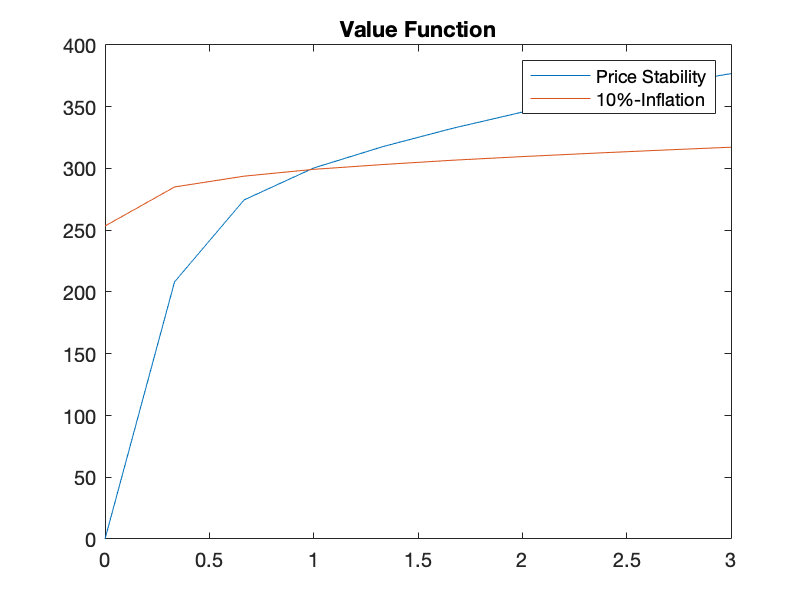

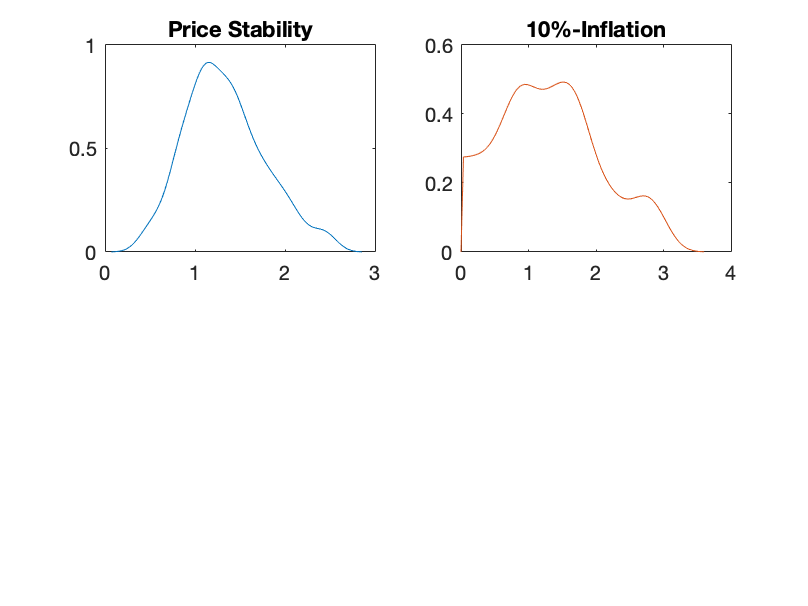

index =      1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20


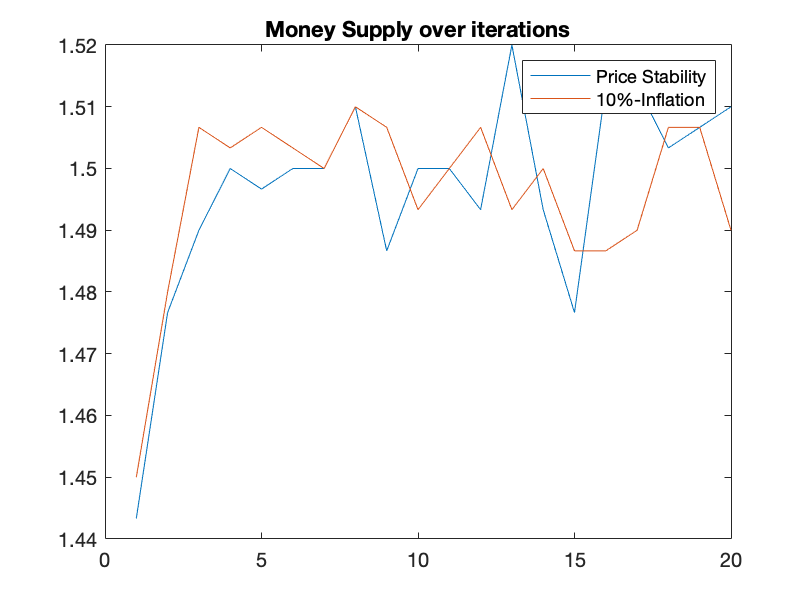

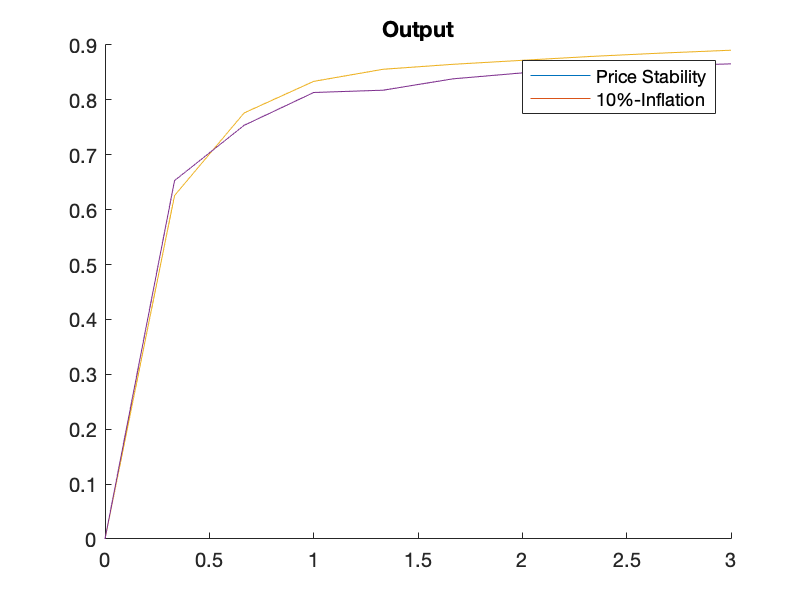

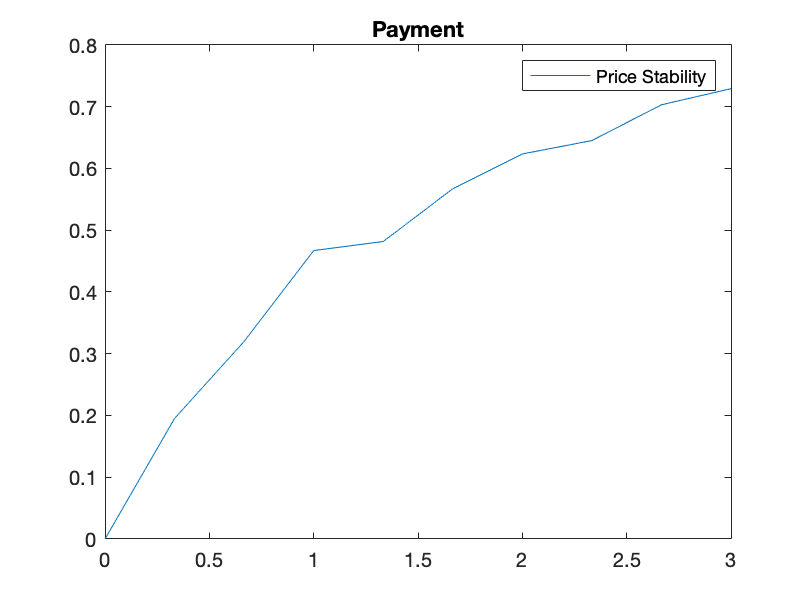

if display_plot_all==1

%Plot V
if display_plot_V==1
figure(1)
plot(m,V_all)
title('Value Function')
legend(mu_labels)

 end


%Plot Distribution Smooth
if display_plot_Distribution_smooth==1 
Distribution_all(Distribution_all==0)=0.001;
    figure(2)
    hold on
for l=1:n_calibration
[f(:,l),xi(:,l)] = ksdensity(Distribution_all(:,l),'Support','positive','BoundaryCorrection'...
    ,'reflection','Bandwidth',std(Distribution_all(:,l))*smoothing_parameter); 
    subplot(2,2,l)
plot(xi(:,l),f(:,l))
title(mu_labels(1,l))
 end
end

hold off

%Plot Distribution Rough
if display_plot_Distribution_rough==1
figure(3)
histogram(Distribution_all,grids*2)
 title('Distribution of Money holdings')
 legend(mu_labels)
 end




%Plot q (first iteration)
 if display_plot_q==1
figure(4)
hold on
plot(m,q_all(:,1,1))
plot(m,q_all(:,round(grids/2),1))
plot(m,q_all(:,grids-1,1))
legend('Seller low', 'Seller middle', 'Seller high')
hold off
title('q')

 end




%Plot d (last iteration)
 if display_plot_d==1
figure(5)
hold on
plot(m,d_all(:,1,1))
plot(m,d_all(:,round(grids/2),1))
plot(m,d_all(:,grids-1,1))
legend('Seller low', 'Seller middle', 'Seller high')
hold off
title('d')
 end

%Plot cdf
if display_plot_cdf==1
figure (6)
plot(m,cdf)
title('cdf')
end


% Plot Money Savings
if display_plot_money_savings==1
m_savings_1=m'-d(:,1);
m_savings_2=m'-d(:,round(grids/2));
m_savings_3=m'-d(:,grids-1);
figure(7)
hold on
plot(m',m_savings_1)
plot(m',m_savings_2)
plot(m',m_savings_3)
legend('Seller low', 'Seller middle', 'Seller high')
hold off
title('Money Savings')
end



% Plot Mettings
if display_plot_meeting==1
for i=1:N
Meeting(1,i)=m(1,Meeting(1,i));
end
figure (8)
histogram(Meeting,grids)
title('Meetings of agents')
end



%Plot M_track_1
if display_plot_M_Track_1==1
index=[1:iterations]
figure(9)
plot(index, M_track_1)
title('Money Supply over iterations')
legend(mu_labels)
end



% Plot all q

 if display_plot_q_all==1
figure(10)
hold on
for j=1:n_calibration
plot(m,q_all(:,5,j))
end
legend(mu_labels)
hold off
title('Output')
 end

% Plot all d


  if display_plot_d_all==1
figure(11)
hold on
for j=1:n_calibration
plot(m,d_all(:,5,j))
end
legend(mu_labels)
title('Payment')
hold off
  end

if display_plot_functional_forms==1
u=Utility(m)
c=cost_function(m)
s=u-c
  figure(12)

hold on
plot(m, u)
plot(m,c)
plot(m,s)
legend('Utility', 'Cost', 'Surplus')
title('Functional Form')
hold off
end



end


time=toc;


## Tables

data_table=[average_q;average_price;std_distribution;velocity; average_real_balances]'

data_table =     0.8514    0.1556    0.4409    0.0877    9.7032
    0.7599    0.5592    0.7384    0.2852    2.6647


figure(20)
 t=uitable(figure,'Data', data_table, 'Position', [100 200 500 200])

t =   Table with properties:

                Data: [2×5 double]
         ColumnWidth: 'auto'
      ColumnEditable: []
    CellEditCallback: ''
            Position: [100 200 500 200]
               Units: 'pixels'

  Show all properties


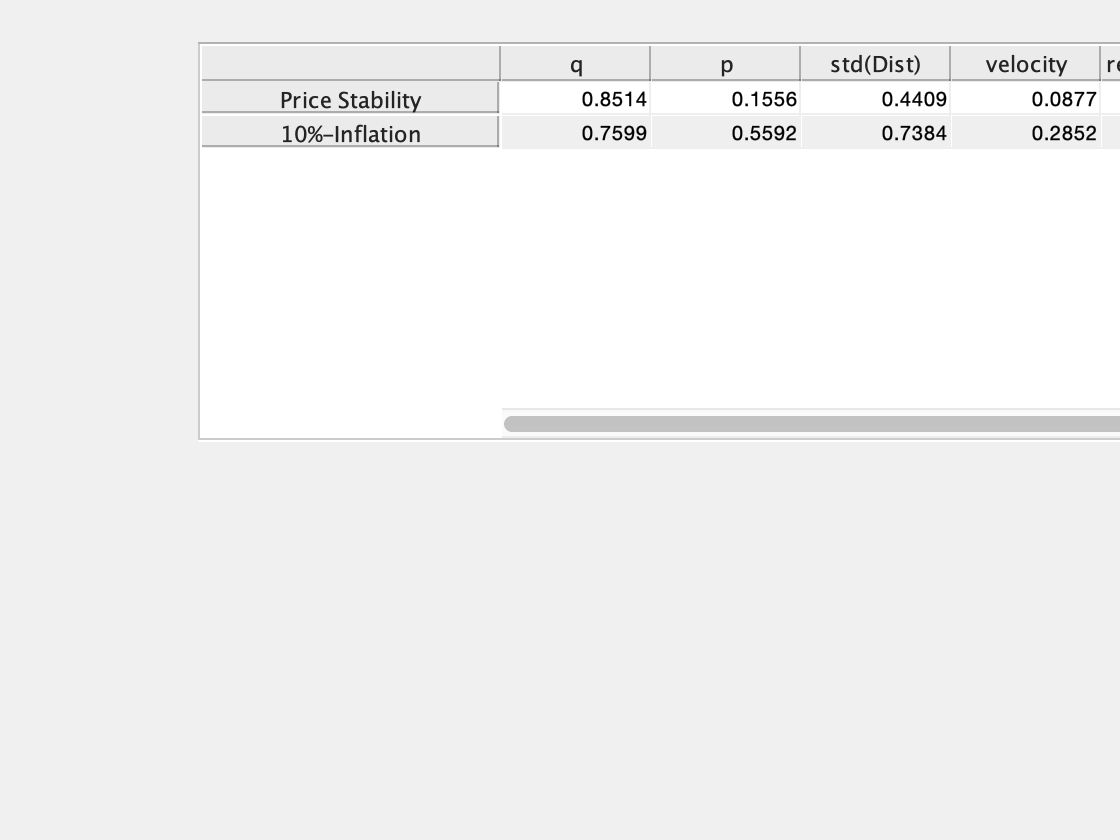

set(t, 'columnname', {'q', 'p','std(Dist)','velocity', 'real balances'})
set(t, 'rowname', mu_labels)

## Welfare Cost of Inflation

W=zeros(1,n_calibration);
for j=2:n_calibration
   [W_1,W_2]=cost_of_Inflation(V_all(:,1),V_all(:,j),q_all(:,:,j),lamdba_all(:,j),alpha,x,0.3)
end

Dif = function_handle with value:
    @(c)(V_stability(i,1)-V_inf(i,1))+(Utility(q_inf(i,:)*lamdba_inf-c)-Utility(q_inf(i,:)*lamdba_inf))



Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>


ans = 0.6188

Dif = function_handle with value:
    @(c)(V_stability(i,1)-V_inf(i,1))+(Utility(q_inf(i,:)*lamdba_inf-c)-Utility(q_inf(i,:)*lamdba_inf))



Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>


ans = 0.7091

Dif = function_handle with value:
    @(c)(V_stability(i,1)-V_inf(i,1))+(Utility(q_inf(i,:)*lamdba_inf-c)-Utility(q_inf(i,:)*lamdba_inf))



Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>


ans = 0.7614

Dif = function_handle with value:
    @(c)(V_stability(i,1)-V_inf(i,1))+(Utility(q_inf(i,:)*lamdba_inf-c)-Utility(q_inf(i,:)*lamdba_inf))



Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>


ans = 0.7681

Dif = function_handle with value:
    @(c)(V_stability(i,1)-V_inf(i,1))+(Utility(q_inf(i,:)*lamdba_inf-c)-Utility(q_inf(i,:)*lamdba_inf))



Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>


ans = 0.7863

Dif = function_handle with value:
    @(c)(V_stability(i,1)-V_inf(i,1))+(Utility(q_inf(i,:)*lamdba_inf-c)-Utility(q_inf(i,:)*lamdba_inf))



Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>


ans = 0.7958

Dif = function_handle with value:
    @(c)(V_stability(i,1)-V_inf(i,1))+(Utility(q_inf(i,:)*lamdba_inf-c)-Utility(q_inf(i,:)*lamdba_inf))



Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>


ans = 0.7991

Dif = function_handle with value:
    @(c)(V_stability(i,1)-V_inf(i,1))+(Utility(q_inf(i,:)*lamdba_inf-c)-Utility(q_inf(i,:)*lamdba_inf))



Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>


ans = 0.8057

Dif = function_handle with value:
    @(c)(V_stability(i,1)-V_inf(i,1))+(Utility(q_inf(i,:)*lamdba_inf-c)-Utility(q_inf(i,:)*lamdba_inf))



Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>


ans = 0.8087

W_1 = 1×10
         0   -1.8708   -0.3620    0.0193    0.2397    0.4074    0.5433    0.6506    0.7393    0.8120


W_2 = 1×10
         0   -3.0234   -0.5104    0.0253    0.3121    0.5182    0.6826    0.8142    0.9176    1.0041
